Wskazniki jakosci

clear ;
close all;

syms s_s

A = [-2, 0; 0, -3]

A =     -2     0
     0    -3


B = [3;0]

B =      3
     0


C = [1, 0.1]

C =     1.0000    0.1000


D = 0

D = 0


x0 = [0; 0]

x0 =      0
     0



%if transmitance
%[A, B, C, D] = tf2ss([1 3], [1 3 2])

A =     -3    -2
     1     0


B =      1
     0


C =      1     3


D = 0

[num, denom] = ss2tf(A, B, C, D);
obj_tf = tf(num, denom)

obj_tf =
 
      s + 3
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



reg_tf = tf([1], [1 0]);

obj_s = poly2sym(num, s_s)/poly2sym(denom, s_s);
reg_s = 1;

transmit_uchyb = @(reg, obj) 1/(1+ reg*obj);
transf_Lapalce_uchyb = @(reg, obj, u_tf) 1/(1+ reg*obj*u_tf);

syms P_s
assume(P_s, 'real')
uchyb_s = simplify(transf_Lapalce_uchyb(reg_s, obj_s, P_s/s_s))

$$uchyb\_s = \frac{1}{\frac{P_{s}\,\left(s_{s}+3\right)}{s_{s}\,\left({s_{s}}^{2}+3\,s_{s}+2\right)}+1}$$

limit(s_s * uchyb_s, s_s, 0, 'right')

$$ans = 0$$



%initial
Kp = 0;
Ki = 1;
Kd = 0;

[zeta,fval]=fmincon(@ISE_opt,[1 2 1],[],[],[],[],[0 0 0],[200 200 200]);


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


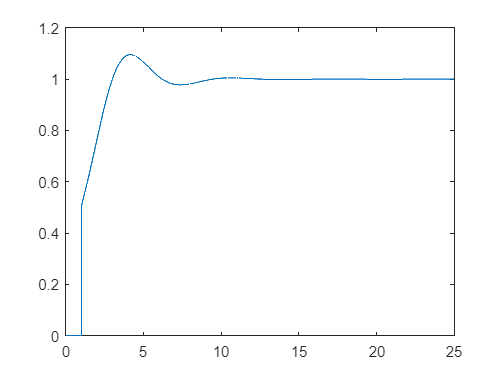

Kp = zeta(1);
Ki = zeta(2);
Kd = zeta(3);
out = sim("uklad_reg.slx");
plot(out.tout, out.y)

function[kpid] = ISE_opt(in)
assignin("base","Kp",0);
assignin("base","Ki",in(2));
assignin("base","Kd",0);
out = sim("uklad_reg.slx");
ISE = out.ISE(end);
kpid = ISE;
end

function[kpid] = ISET_opt(in)
assignin("base","Kp",in(1));
assignin("base","Ki",in(2));
assignin("base","Kd",0);
out = sim("uklad_reg.slx");
ISET = out.ISET(end);
kpid = ISET;
end

function[kpi] = regtime(in)
assignin("base","Kp",in(1));
assignin("base","Ki",in(2));
assignin("base","Kd",0);
out = sim("uklad_reg.slx");
y = out.y(end);
eabs = abs(out.y - out.y(end));
absyinf = abs(out.y(end));
regtime = out.tout(max(find(eabs > 0.05*absyinf)));
kpi = regtime;
end